# Detectar coches en un vídeo de tráfico

En este ejemplo se muestra cómo utilizar Image Processing Toolbox™ para visualizar y analizar vídeos o secuencias de imágenes. En este ejemplo se utiliza (MATLAB®), y otras funciones de Image Processing Toolbox para detectar coches de color claro en un vídeo de tráfico.`VideoReader``implay` Tenga en cuenta que tiene capacidades específicas de la plataforma y es posible que no pueda leer el vídeo Motion JPEG2000 suministrado en algunas plataformas.`VideoReader`

**Paso 1: Accede a vídeo con VideoReader**

La función construye un objeto de lector multimedia que puede leer datos de vídeo de un archivo multimedia.`VideoReader` Consulte para obtener información sobre qué formatos son compatibles con su plataforma.[`VideoReader`](https://la.mathworks.com/help/matlab/ref/videoreader.html)

Se utiliza para acceder al vídeo y obtener información básica al respecto.`VideoReader`

trafficVid = VideoReader('traffic.mj2')

trafficVid =   VideoReader with properties:

   General Properties:
            Name: 'traffic.mj2'
            Path: 'C:\Program Files\MATLAB\R2021a\toolbox\images\imdata'
        Duration: 8
     CurrentTime: 0
       NumFrames: 120

   Video Properties:
           Width: 160
          Height: 120
       FrameRate: 15
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


El método get proporciona más información sobre el vídeo, como su duración en segundos.

get(trafficVid)

obj =   VideoReader with properties:

   General Properties:
            Name: 'traffic.mj2'
            Path: 'C:\Program Files\MATLAB\R2021a\toolbox\images\imdata'
        Duration: 8
     CurrentTime: 0
       NumFrames: 120

   Video Properties:
           Width: 160
          Height: 120
       FrameRate: 15
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


**Paso 2: Explora el vídeo con IMPLAY**

Explora el video en .`implay`

%implay('traffic.mj2');

**Paso 3: Desarrolle su algoritmo**

Al trabajar con datos de vídeo, puede ser útil seleccionar un fotograma representativo del vídeo y desarrollar el algoritmo en ese fotograma. A continuación, este algoritmo se puede aplicar al procesamiento de todos los fotogramas del vídeo.

Para esta aplicación de etiquetado de automóviles, examine un marco que incluya tanto coches de color claro como de color oscuro. Cuando una imagen tiene muchas estructuras, como los fotogramas de vídeo de tráfico, es útil simplificar la imagen tanto como sea posible antes de intentar detectar un objeto de interés. Una manera de hacer esto para la aplicación de etiquetado de coches es suprimir todos los objetos en la imagen que no son coches de color claro (coches de color oscuro, carriles, hierba, etc.). Normalmente, se necesita una combinación de técnicas para eliminar estos objetos extraños.

Una forma de eliminar los coches de color oscuro de los marcos de vídeo es utilizar la función.`imextendedmax` Esta función devuelve una imagen binaria que identifica regiones con valores de intensidad por encima de un umbral especificado, denominado maxima regional. Todos los demás objetos de la imagen con valores de píxel por debajo de este umbral se convierten en el fondo. Para eliminar los coches de color oscuro, determine el valor medio de píxel para estos objetos en la imagen. (Utilícelo para convertir el vídeo original de RGB a escala de grises.)`rgb2gray` Puede utilizar la herramienta de región de píxeles para ver los valores de píxel.`implay` Especifique el valor medio de píxel (o un valor ligeramente superior) como umbral al llamar a .`imextendedmax` Para este ejemplo, establezca el valor en 50.

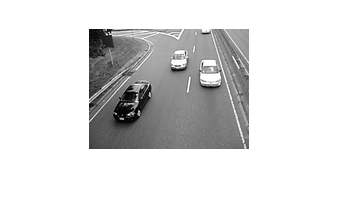

darkCarValue = 50;
darkCar = rgb2gray(read(trafficVid,71));
noDarkCar = imextendedmax(darkCar, darkCarValue);
imshow(darkCar)

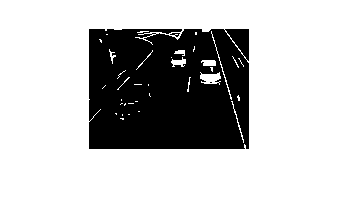

figure
imshow(noDarkCar)

En la imagen procesada, observe cómo se eliminan la mayoría de los objetos de automóviles de color oscuro, pero quedan muchos otros objetos extraños, en particular las marcas de carril. El procesamiento de máximas regionales no eliminará las marcas de carril porque sus valores de píxel están por encima del umbral. Para eliminar estos objetos, puede utilizar la función morfológica `imopen` Esta función utiliza el procesamiento morfológico para eliminar objetos pequeños de una imagen binaria conservando objetos grandes. Al utilizar el procesamiento morfológico, debe decidir el tamaño y la forma del elemento de estructuración utilizado en la operación. Dado que las marcas de carril son objetos largos y delgados, utilice un elemento de estructuración en forma de disco con radio correspondiente a la anchura de las marcas de carril. Puede utilizar la herramienta de región de píxeles para estimar el ancho de estos objetos.`implay` Para este ejemplo, establezca el valor en 2.

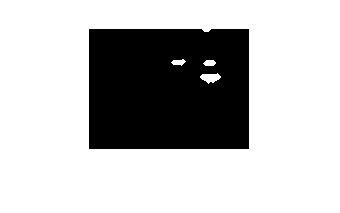

sedisk = strel('disk',2);
noSmallStructures = imopen(noDarkCar, sedisk);
imshow(noSmallStructures)

Para completar el algoritmo, utilice para encontrar el centroide de los objetos en (debe ser sólo los coches de color claro).`regionpropsnoSmallStructures` Utilice esta información para colocar la etiqueta en los coches de color claro en el vídeo original.

**Paso 4: Aplicar el algoritmo al vídeo**

La aplicación de etiquetado de automóviles procesa el vídeo de un fotograma a uno en un bucle. (Debido a que un vídeo típico contiene un gran número de fotogramas, se necesitaría mucha memoria para leer y procesar todos los fotogramas a la vez.)

Un pequeño vídeo (como el de este ejemplo) podría procesarse a la vez, y hay muchas funciones que proporcionan esta capacidad. Para obtener más información, consulte .[Procesar secuencias de imágenes](https://la.mathworks.com/help/images/what-is-an-image-sequence.html#brcvajp)

Para un procesamiento más rápido, preasigna la memoria utilizada para almacenar el vídeo procesado.

nframes = trafficVid.NumFrames;
I = read(trafficVid, 1);
taggedCars = zeros([size(I,1) size(I,2) 3 nframes], class(I));

for k = 1 : nframes
    singleFrame = read(trafficVid, k);
    
    % Convert to grayscale to do morphological processing.
    I = rgb2gray(singleFrame);
    
    % Remove dark cars.
    noDarkCars = imextendedmax(I, darkCarValue); 
    
    % Remove lane markings and other non-disk shaped structures.
    noSmallStructures = imopen(noDarkCars, sedisk);

    % Remove small structures.
    noSmallStructures = bwareaopen(noSmallStructures, 150);
   
    % Get the area and centroid of each remaining object in the frame. The
    % object with the largest area is the light-colored car.  Create a copy
    % of the original frame and tag the car by changing the centroid pixel
    % value to red.
    taggedCars(:,:,:,k) = singleFrame;
   
    stats = regionprops(noSmallStructures, {'Centroid','Area'});
    if ~isempty([stats.Area])
        areaArray = [stats.Area];
        [junk,idx] = max(areaArray);
        c = stats(idx).Centroid;
        c = floor(fliplr(c));
        width = 2;
        row = c(1)-width:c(1)+width;
        col = c(2)-width:c(2)+width;
        taggedCars(row,col,1,k) = 255;
        taggedCars(row,col,2,k) = 0;
        taggedCars(row,col,3,k) = 0;
    end
end

**Paso 5: Visualizar resultados**

Obtener la velocidad de fotogramas del vídeo original y utilizarlo para ver en .`taggedCars``implay`

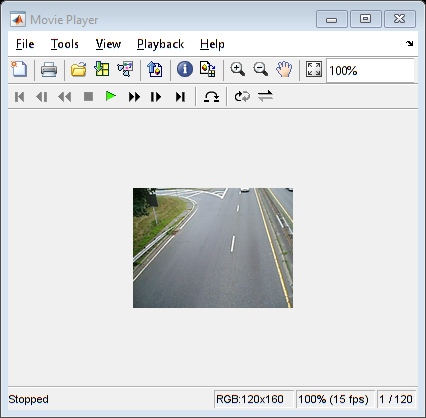

frameRate = trafficVid.FrameRate;
implay(taggedCars,frameRate);